cd /home/ben/Music/Cleaned_audio
data = audioread("FVB109_1023.wav")

data =          0
   -0.0000
         0
    0.0000
    0.0001
   -0.0002
   -0.0002
    0.0001
    0.0000
    0.0000


load('volt2pascal.mat')

cd /media/ben/'Extreme SSD'/analysisData/added_aligned
load('FVB109_1023.mat')
load("condUnits_FVB109_1023.mat")

%create the figure of sound and units across the conditons

samples_aggregated = [adjustedSamples.Aluminum;adjustedSamples.Attenuated;adjustedSamples.noObject;adjustedSamples.NoWhisking];
sdf_aggregated = [referance_table.AluminumSDF{28};referance_table.AttenuatedSDF{28};referance_table.NoObjectSDF{28};referance_table.NoWhiskingSDF{28}]';

samples_aggregated = double(samples_aggregated);

k = 6;
sdf_aggregated(2,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 29;
sdf_aggregated(3,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 17;
sdf_aggregated(4,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 11;
sdf_aggregated(5,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 2;
sdf_aggregated(6,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 19;
sdf_aggregated(7,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 22;
sdf_aggregated(8,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 24;
sdf_aggregated(9,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 25;
sdf_aggregated(10,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';
k = 26;
sdf_aggregated(11,:) = [referance_table.AluminumSDF{k};referance_table.AttenuatedSDF{k};referance_table.NoObjectSDF{k};referance_table.NoWhiskingSDF{k}]';



[samp_ordered,idx] = sort(samples_aggregated,'ascend');

sdf_reordered = sdf_aggregated(:,idx)

sdf_reordered =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

[~,startInd] = min(abs(samp_ordered - 14816000))

startInd = 308300

[~,endInd] = min(abs(samp_ordered-42280400))

endInd = 1148239

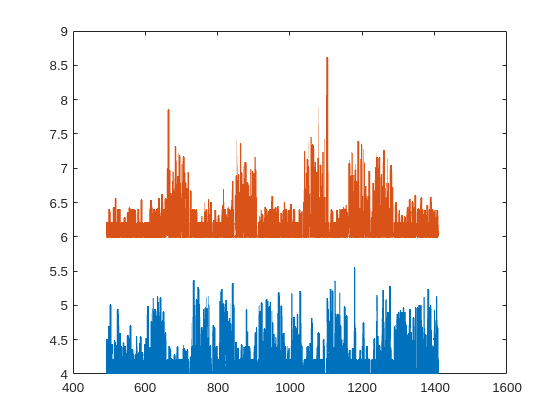

h = figure;
plot(samp_ordered(startInd:endInd)/30000,(sdf_reordered(1,startInd:endInd)/100)+4,'LineWidth',1.5)
hold on
plot(samp_ordered(startInd:endInd)/30000,(sdf_reordered(2,startInd:endInd)/100)+6,'LineWidth',1.5)
hold on

whisking = experiment.Whisking.smoothed(1:697699)

whisking =    33.0774   33.0687   33.0511   33.0248   32.9930   32.9606   32.9310   32.9072   32.8913   32.8826   32.8783   32.8754   32.8721   32.8684   32.8645   32.8602   32.8547   32.8480   32.8413   32.8370   32.8366   32.8393   32.8433   32.8473   32.8511   32.8548   32.8567   32.8541   32.8434   32.8224   32.7920   32.7669   32.7479   32.7316   32.7149   32.7008   32.6978   32.7088   32.7293   32.7503   32.7627   32.7632   32.7611   32.7680   32.7826   32.7988   32.8111   32.8168   32.8156   32.8082


soundChanges = round(alignedTimes.alignedEphys(experiment.Conditions.all_changes))'

soundChanges =     39339895
    55088043
    70836191
    86484344
   102232491
   117830680
   133478850
   149227006
   164875534
   180623698


soundDispose(:,1) = soundChanges-3*250000;
soundDispose(:,2) = soundChanges+2*250000;

soundStart = round(experiment.timeStamp.alignedEphys(14816000))

soundStart = 123606935

soundEnd = round(experiment.timeStamp.alignedEphys(42280400))

soundEnd = 352503550

soundCut = data.*transferFunction./gainF;

soundCutMedian = median(soundCut);
for i=2:length(soundDispose)
    soundCut(soundDispose(i,1):soundDispose(i,2)) = soundCutMedian;
end

Nonfinite endpoints or increment for colon operator in index.

soundCutEnv = soundCut(soundStart:soundEnd)*10;

soundCutEnv(abs(soundCutEnv) > 1.5) = soundCutMedian*10;


h = figure;
hold on;

maxY = 10

maxY = 10

most_events = max([length(experiment.conditionVector.aluminumEpochs), ...
    length(experiment.conditionVector.mutedEpochs) ...
    ,length(experiment.conditionVector.nonEpochs) ...
    ,length(experiment.conditionVector.noWhiskingEpochs)])

most_events = 47

for i = 1:most_events
    try
        startXAl = experiment.conditionVector.aluminumEpochs(i, 1)/30000;
        endXAl = experiment.conditionVector.aluminumEpochs(i, 2)/30000;
        fill([startXAl, endXAl, endXAl, startXAl], [-1.3, -1.3, maxY, maxY],'r','FaceColor',colorBen.aluminum,'FaceAlpha',0.5,'EdgeColor','none');
    end
    try
        startXAt = experiment.conditionVector.mutedEpochs(i, 1)/30000;
        endXAt = experiment.conditionVector.mutedEpochs(i, 2)/30000;
        fill([startXAt, endXAt, endXAt, startXAt], [-1.3, -1.3, maxY, maxY],'b','FaceColor',colorBen.muted, 'FaceAlpha', 0.5, 'EdgeColor', 'none');
    end
    try
        startXNo = experiment.conditionVector.nonEpochs(i, 1)/30000;
        endXNo = experiment.conditionVector.nonEpochs(i, 2)/30000;
        fill([startXNo, endXNo, endXNo, startXNo], [0-1.3, 0-1.3, maxY, maxY],'y','FaceColor',colorBen.non, 'FaceAlpha', 0.5, 'EdgeColor', 'none');

    end
    try
        startXNW = experiment.conditionVector.noWhiskingEpochs(i, 1)/30000;
        endXNW = experiment.conditionVector.noWhiskingEpochs(i, 2)/30000;
        fill([startXNW, endXNW, endXNW, startXNW], [-1.3, -1.3, maxY, maxY],'y','FaceColor','k', 'FaceAlpha', 0.15, 'EdgeColor', 'none');

    end
end
plot(experiment.Cams.whisking.csv_aligned_frames/30000,(whisking/50)-1.2,'Color',colorBen.green,'LineWidth',1.5)
hold on;

plot([soundStart:soundEnd]/250000,soundCutEnv+2,'Color',colorBen.purple,'LineWidth',1.25)
plot(samp_ordered(startInd:endInd)/30000,(sdf_reordered(1,startInd:endInd)/100)+4,'LineWidth',1.5,'Color',[0 0.4470 0.7410])
hold on
plot(samp_ordered(startInd:endInd)/30000,(sdf_reordered(2,startInd:endInd)/100)+6,'LineWidth',1.5,'Color',[0.8500 0.3250 0.0980])
hold on

xticks([])
yticks([-1,2 4.2 6.2 8])
yticklabels({'whisking (a.u.)','sound (Pa)','unit 144 SDF (Hz)','unit 122 SDF (Hz)'})
axis on;
set(gca,'Fontsize',20,'FontName','SansSerif')
set(gcf,'Position',[2267,71,1058,807]);
xlim([495,1409])
ylim([-1.3 7.5])
plot([1408,1408],[4 4.5],'k','LineWidth',2)
text(1425,4,'50Hz','FontSize',16,'Rotation',90,'FontName','SansSerif')
plot([1408,1408],[2 2.5],'k','LineWidth',2)
text(1425,2,'0.05Pa','FontSize',16,'Rotation',90,'FontName','SansSerif')
plot([1409-60 1409],[-1.25 -1.25],'k','LineWidth',2)
text(1409-30,-1.5,'60s','FontSize',16)